k = 4;
d = 30;
n = 5;

options.method = "random_no_offset";
options.epsilon = 1/10;

T_seq = 1e5;
m = 150;

covNorm = zeros(m, 4);
Cost = zeros(m, 4);


options.maxIter = 2500;
options.tol = 1e-14;
options.th_relerr = 1e-7;

alpha = 0.1;
rho = 0.90;


T_hats = cell(n,1);
O_hats = cell(n,1);
T_hat = zeros(k,k);

P3 = cell(n,1);

load("PerformanceTests/CorrelationPerformance");

for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, n, options);
    
    cov = 0;
    
    for ii = 1:n
        cov = (1/n) * sum(corrcoef(O{ii}), "all")/(k*k);
    end

    covNorm(i, 1) = cov;

    [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end

    % Uncoupled CPD
    T_hat = zeros(k,k);
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';
    end

    Cost(i, 1) = HMMError(T, O, T_hat, O_hats, false);  
    
end

Processing:  000%  |                                      | 0/150it [00:00:00<Inf:NaN:NaN, Inf it/s]



options.method = "random";

for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, n, options);
    
    cov = 0;
    
    for ii = 1:n
        cov = (1/n) * sum(corrcoef(O{ii}), "all")/(k*k);
    end

    covNorm(i, 3) = cov;

    [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);

    for ii = 1:n
        P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
    end

    T_hat = zeros(k,k);
    % Uncoupled CPD
    for ii = 1:n
        [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, options);
        O_hat = Stochasticize(B);
        T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
    
        Pbest = PermutationFit(T, T_hats{ii}, true);
        T_hats{ii} = Pbest * T_hats{ii} * Pbest';
        T_hat = T_hat + (1/n) * T_hats{ii};
    
        O_hats{ii} = O_hat * Pbest';
    end

    Cost(i, 3) = HMMError(T, O, T_hat, O_hats, false);  
end

Processing:  000%  |                                      | 0/150it [00:00:00<Inf:NaN:NaN, Inf it/s]





save("PerformanceTests/CorrelationPerformance", "covNorm", "Cost")

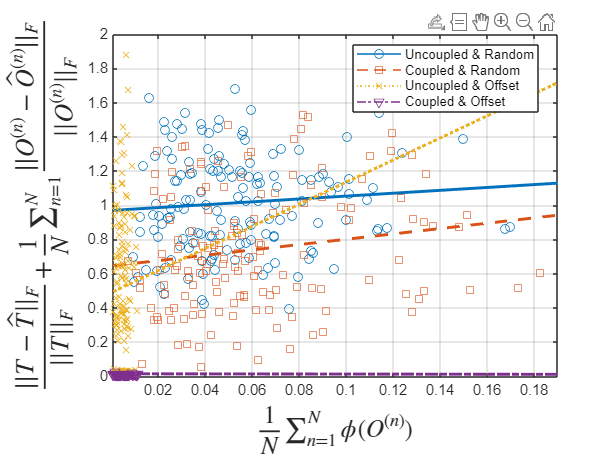



px = [0.0008 0.19];

cmap = orderedcolors("gem");

figure()
py = polyval(polyfit(covNorm(:, 1), Cost(:, 1), 1), px);
plot(covNorm(:,1), Cost(:, 1), 'o', 'color', cmap(1, :)); hold on;
plot(px, py, '-', 'LineWidth', 2, 'color', cmap(1, :)); hold on;

py = polyval(polyfit(covNorm(:, 2), Cost(:, 2), 1), px);
plot(covNorm(:,2), Cost(:, 2), 's', 'color', cmap(2, :)); hold on;
loglog(px, py, '--', 'LineWidth', 2, 'color', cmap(2, :)); hold on;


py = polyval(polyfit(covNorm(:, 3), Cost(:, 3), 1), px);
plot(covNorm(:,3), Cost(:, 3), 'x', 'color', cmap(3, :)); hold on;
loglog(px, py, ':', 'LineWidth', 2, 'color', cmap(3, :)); hold on;


py = polyval(polyfit(covNorm(:,4), Cost(:, 4), 1), px);
plot(covNorm(:,4), Cost(:, 4), 'v', 'color', cmap(4, :)); hold on;
loglog(px, py, '-.', 'LineWidth', 2, 'color', cmap(4, :)); hold on;

grid on; xlim(px);
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',18,'FontWeight','bold')
xlabel("$\frac{1}{N}\sum_{n=1}^N\phi(O^{(n)})$", "Interpreter","latex",'FontSize',17,'FontWeight','bold')

qw{1} = plot(nan, '-o', 'color', cmap(1, :));
qw{2} = plot(nan, '--s', 'color', cmap(2, :));
qw{3} = plot(nan, ':x', 'color', cmap(3, :));
qw{4} = plot(nan, '-.v', 'color', cmap(4, :)); 
legend([qw{:}], {"Uncoupled & Random", "Coupled & Random", "Uncoupled & Offset", "Coupled & Offset"}, 'location', 'best')



k = 4;
d = 30;
n = 5;
% m = 1e5;

hmm_options.epsilon = 1/7;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

ps = 20;
sampleArray = ceil(logspace(3, 7, ps));

BWmax = 10;
Nruns = 20;


% save("PerformanceTests/Time_Performance_Costs", "BWCost", "UncoupledCost", "CoupledCost", "TensorCost")

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;


T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);
Dspace = zeros(n,d);

load("PerformanceTests/Time_Performance_Costs2");




for j = 1:Nruns
    for i = progress(1:ps)
        [T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);

        [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, sampleArray(i));

        
        tic
        for ii = 1:n
            P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
        end
        JPTTime(i, j) = toc;

     
        % Uncoupled CPD
        tic
        T_hat = zeros(k,k);
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O, T_hat, O_hats, false);  
        UncoupledTime(i, j) = toc;
    end
end

Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/20it [00:00:00<Inf:NaN:NaN,


save("PerformanceTests/Time_Performance_Costs2", "BWCost", "BWTime", "UncoupledCost", "UncoupledTime", "CoupledCost", "CoupledTime", "JPTTime", "BWmax", "sampleArray");


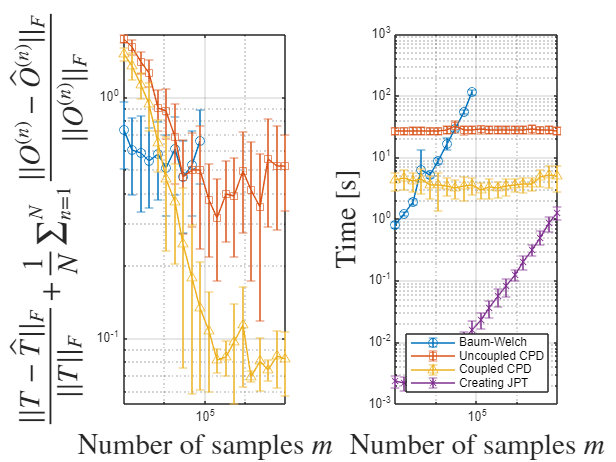

load("PerformanceTests/Time_Performance_Costs2");

[BWCostSTD, BWCostMean] = std(BWCost, 0, 2);
[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);

[BWTimeSTD, BWTimeMean] = std(BWTime, 0, 2);
[UncoupledTimeSTD, UncoupledTimeMean] = std(UncoupledTime, 0, 2);
[CoupledTimeSTD, CoupledTimeMean] = std(CoupledTime, 0, 2);
[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2);

figure()
subplot(1, 2, 1)

errorbar(sampleArray(1:BWmax)', BWCostMean, BWCostSTD/2, "-o"); hold on;
errorbar(sampleArray', UncoupledCostMean, UncoupledCostSTD/2, "-s"); hold on;
errorbar(sampleArray', CoupledCostMean, CoupledCostSTD/2, "-^");
set(gca,'YScale','log', 'XScale', 'log');
grid on;
% title("HMM error over samples",'FontSize',24,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

subplot(1, 2, 2)
errorbar(sampleArray(1:BWmax)', BWTimeMean, BWTimeSTD/2, "-o"); hold on;
errorbar(sampleArray', UncoupledTimeMean, UncoupledTimeSTD/2, "-s"); hold on;
errorbar(sampleArray', CoupledTimeMean, CoupledTimeSTD/2, "-^"); hold on;
errorbar(sampleArray', JPTTimeMean, JPTTimeSTD/2, "-x");

set(gca,'YScale','log', 'XScale', 'log');
grid on; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast")
% title("Calculation time over samples",'FontSize',24,'FontWeight','bold')
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')

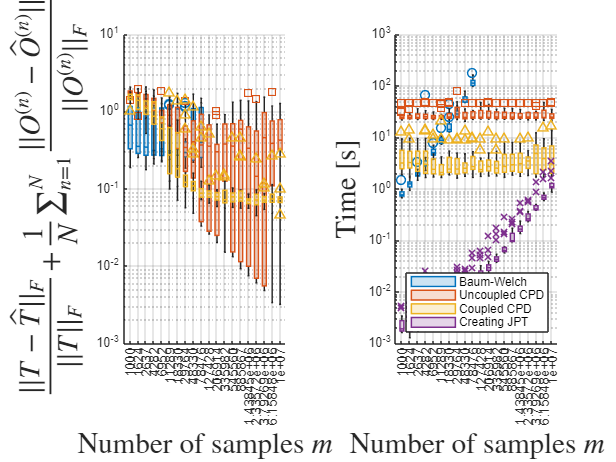


figure()
subplot(1, 2, 1)
cmap = orderedcolors("gem");

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(sampleArray);

set(gca,'YScale','log');

grid on;
% title("HMM error over samples",'FontSize',24,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

subplot(1, 2, 2)

boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(sampleArray);

set(gca,'YScale','log');
grid on; 
legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");
% title("Calculation time over samples",'FontSize',24,'FontWeight','bold')
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("Number of samples $m$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')

k = 4;
d = 30;
n = 5;
m = 1e5;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.05;
rho = 0.85;

Krange = 2:9;

Nruns = 20;
ps = length(Krange);

JPTTime = zeros(ps, Nruns);

BWCost = zeros(ps, Nruns);
BWTime = zeros(ps, Nruns);

UncoupledCost = zeros(ps, Nruns);
UncoupledTime = zeros(ps, Nruns);

CoupledCost = zeros(ps, Nruns);
CoupledTime = zeros(ps, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);

load("PerformanceTests/PerformanceOverStates")

for j = 1:Nruns
    for i = progress(1:length(Krange))
        k = Krange(i);

        [T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);
        [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, m);

        
        tic
        for ii = 1:n
            P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
        end
        JPTTime(i, j) = toc;



        % Uncoupled CPD
        T_hat = zeros(k,k);
        tic
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O, T_hat, O_hats, false);  
        UncoupledTime(i, j) = toc;
    end
end

Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                          | 0/8it [00:00:00<In


save("PerformanceTests/PerformanceOverStates", "BWCost", "BWTime", "UncoupledCost", "UncoupledTime", "CoupledCost", "CoupledTime", "JPTTime", "Krange");


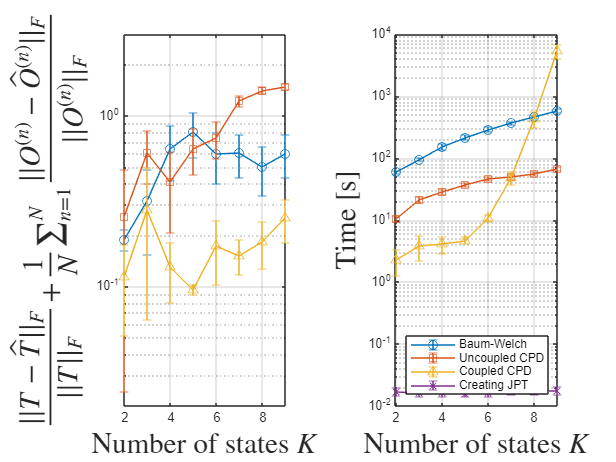

load("PerformanceTests/PerformanceOverStates")


[BWCostSTD, BWCostMean] = std(BWCost, 0, 2);
[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);

[BWTimeSTD, BWTimeMean] = std(BWTime, 0, 2);
[UncoupledTimeSTD, UncoupledTimeMean] = std(UncoupledTime, 0, 2);
[CoupledTimeSTD, CoupledTimeMean] = std(CoupledTime, 0, 2);
[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2);

figure()
subplot(1, 2, 1)

errorbar(Krange, BWCostMean, BWCostSTD/2, "-o"); hold on;
errorbar(Krange, UncoupledCostMean, UncoupledCostSTD/2, "-s"); hold on;
errorbar(Krange, CoupledCostMean, CoupledCostSTD/2, "-^");
set(gca,'YScale','log');
grid on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Cost over $K$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;
ylim([0.02 3])
xlim([min(Krange)-0.01 max(Krange) + 0.01])

subplot(1, 2, 2)
errorbar(Krange, BWTimeMean, BWTimeSTD/2, "-o"); hold on;
errorbar(Krange, UncoupledTimeMean, UncoupledTimeSTD/2, "-s"); hold on;
errorbar(Krange, CoupledTimeMean, CoupledTimeSTD/2, "-^"); hold on;
errorbar(Krange, JPTTimeMean, JPTTimeSTD/2, "-x");

set(gca,'YScale','log');
grid on; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast")
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Time over $K$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlim([min(Krange)-0.01 max(Krange) + 0.01])

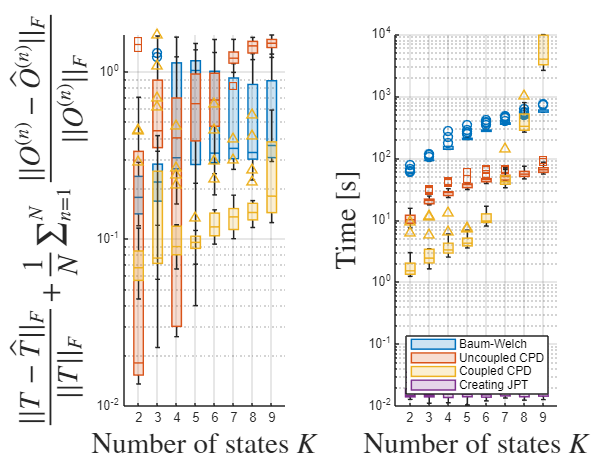


cmap = orderedcolors("gem");

figure()
subplot(1, 2, 1)
boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(Krange);

set(gca,'YScale','log');

grid on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Cost over $K$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
hold off;

subplot(1, 2, 2)
boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(Krange);

set(gca,'YScale','log');
grid on; 
legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Time over $K$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of states $K$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')

k = 4;
d = 30;
m = 1e5;

Nruns = 20;


load("PerformanceTests/PerformanceOverSequences")


for j = 1:Nruns
    j
    for i = progress(1:length(Nrange))

        n = Nrange(i);

        [T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);
        [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, m);
        
        tic
        for ii = 1:n
            P3{ii} = ProbabilityTensorGenerate(seq(ii, :), 3, d);
        end
        JPTTime(i, j) = toc;


        % Uncoupled CPD
        tic
        T_hat = zeros(k,k);
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O, T_hat, O_hats, false);  
        UncoupledTime(i, j) = toc;
    end
end

j = 1

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 2

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 3

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 4

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 5

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 6

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 7

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 8

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 9

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 10

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 11

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 12

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 13

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 14

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 15

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 16

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 17

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 18

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 19

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]

j = 20

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]


save("PerformanceTests/PerformanceOverSequences", "BWCost", "BWTime", "UncoupledCost", "UncoupledTime", "CoupledCost", "CoupledTime", "JPTTime", "Nrange");

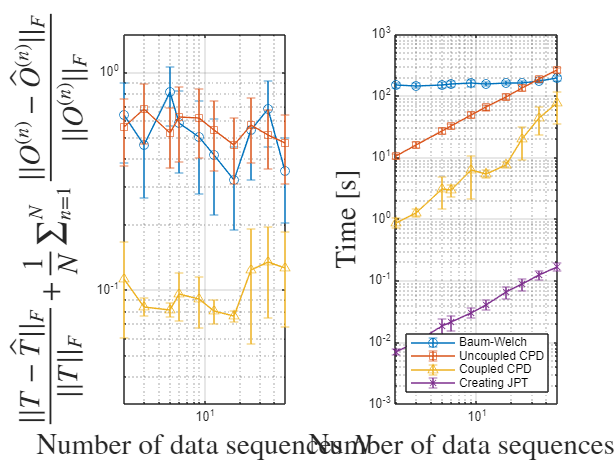


load("PerformanceTests/PerformanceOverSequences")

[BWCostSTD, BWCostMean] = std(BWCost, 0, 2);
[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);

[BWTimeSTD, BWTimeMean] = std(BWTime, 0, 2);
[UncoupledTimeSTD, UncoupledTimeMean] = std(UncoupledTime, 0, 2);
[CoupledTimeSTD, CoupledTimeMean] = std(CoupledTime, 0, 2);
[JPTTimeSTD, JPTTimeMean] = std(JPTTime, 0, 2);

figure()
subplot(1, 2, 1)
cmap = orderedcolors("gem");

errorbar(Nrange, BWCostMean, BWCostSTD/2, "-o"); hold on;
errorbar(Nrange, UncoupledCostMean, UncoupledCostSTD/2, "-s"); hold on;
errorbar(Nrange, CoupledCostMean, CoupledCostSTD/2, "-^"); hold on;

set(gca,'YScale','log', 'XScale', 'log');

grid on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Cost over $N$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of data sequences $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold');
xlim([min(Nrange) - 0.01 max(Nrange) + 0.01])
ylim([0.03 1.5])
hold off;

subplot(1, 2, 2)
errorbar(Nrange, BWTimeMean, BWTimeSTD/2, "-o"); hold on;
errorbar(Nrange, UncoupledTimeMean, UncoupledTimeSTD/2, "-s"); hold on;
errorbar(Nrange, CoupledTimeMean, CoupledTimeSTD/2, "-^"); hold on;
errorbar(Nrange, JPTTimeMean, JPTTimeSTD/2, "-x");

set(gca,'YScale','log', 'XScale', 'log');
grid on; legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast")
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Time over $N$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of data sequences $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlim([min(Nrange) - 0.01 max(Nrange) + 0.01])

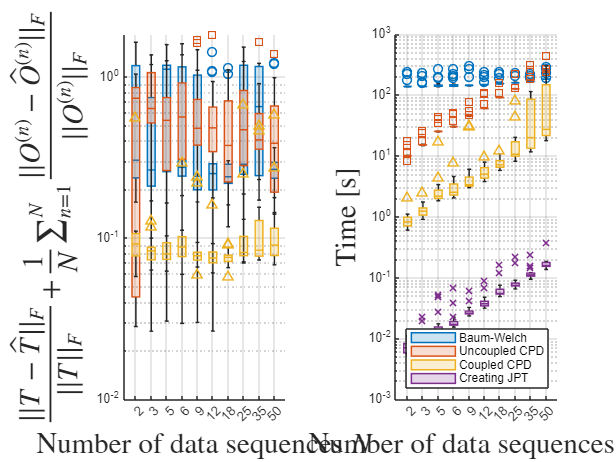



figure()
subplot(1, 2, 1)
cmap = orderedcolors("gem");

% boxplot(BWCost', Nrange, 'Symbol', 'o', Colors=cmap(1, :)); hold on;
% boxplot(UncoupledCost', Nrange, 'Symbol', 's', Colors=cmap(2, :)); hold on;
% boxplot(CoupledCost', Nrange, 'Symbol', '^', Colors=cmap(3, :)); hold on;

boxchart(BWCost', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(Nrange);

set(gca,'YScale','log');

grid on;
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Cost over $N$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of data sequences $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold');
hold off;

subplot(1, 2, 2)
% boxplot(BWTime', Nrange, 'Symbol', 'o', Colors=cmap(1, :)); hold on;
% boxplot(UncoupledTime', Nrange, 'Symbol', 's', Colors=cmap(2, :)); hold on;
% boxplot(CoupledTime', Nrange, 'Symbol', '^', Colors=cmap(3, :)); hold on;
% boxplot(JPTTime', Nrange, 'Symbol', 'x', Colors=cmap(4, :)); hold on;

boxchart(BWTime', "MarkerStyle", 'o'); hold on;
boxchart(UncoupledTime', "MarkerStyle", 's'); hold on;
boxchart(CoupledTime', "MarkerStyle", '^'); hold on;
boxchart(JPTTime', "MarkerStyle", 'x'); hold on;
xticklabels(Nrange);

set(gca,'YScale','log');
grid on; 
legend("Baum-Welch", "Uncoupled CPD", "Coupled CPD", "Creating JPT", Location="southeast");
ylabel("Time [s]", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
% title("Time over $N$","Interpreter","latex",'FontSize',24,'FontWeight','bold')
xlabel("Number of data sequences $N$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')